% -- 1. CLEAR WORKSPACE --
clear; clc; close all;

% -- 1a. READ IMAGE --
img = imread('Image4.jpg');  % Adjust the file name/path as needed.
DEBUG = true;                % Debug flag

%% 2. Resize image if larger than 1280x720
[origH, origW, ~] = size(img);
maxW = 1280;
maxH = 720;
if (origW > maxW || origH > maxH)
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

Image resized from (855, 1500) to (720, 1264)


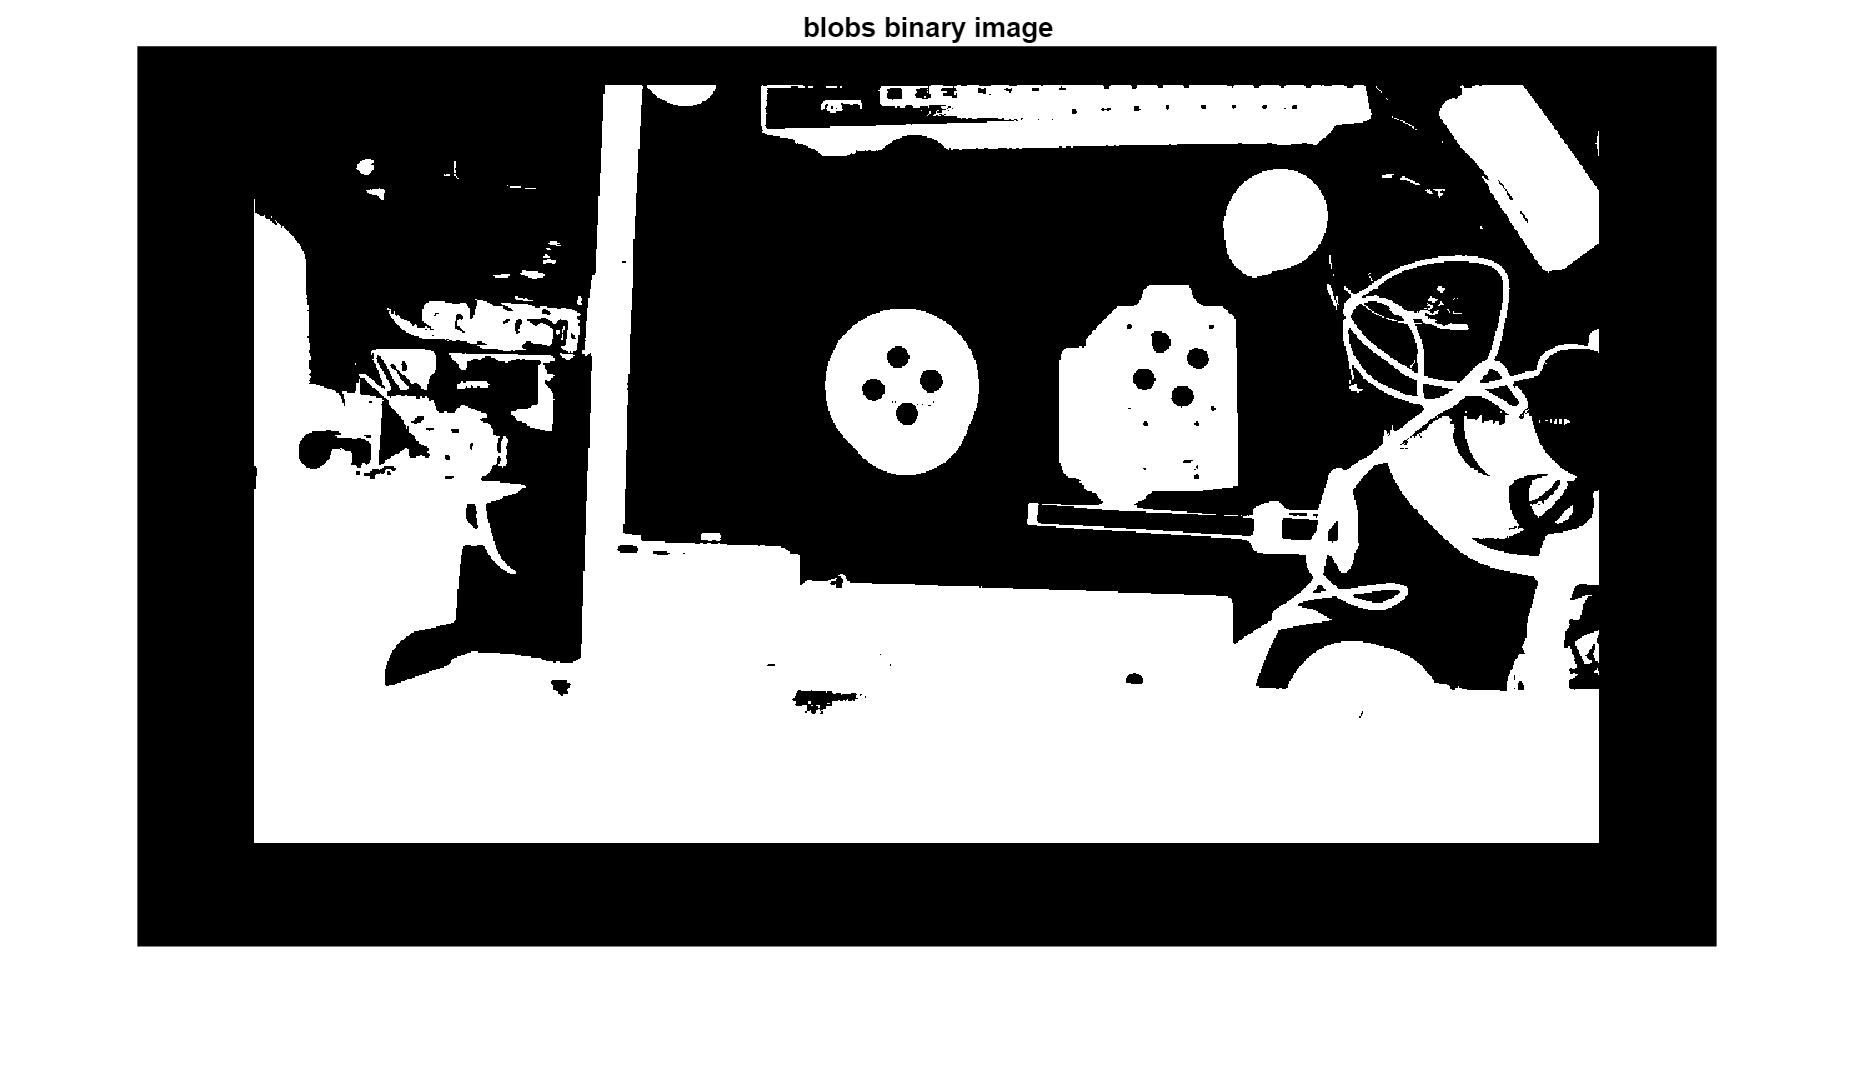


%% 3. Simple Grayscale Threshold (binImg) - Inverted
grayImg = rgb2gray(img);
level = 0.4;                % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;            % Invert => dark objects become white=1

% (Optional) Show blobs detection
if DEBUG
    figure;
    imshow(binImg);
    title('blobs binary image');
end

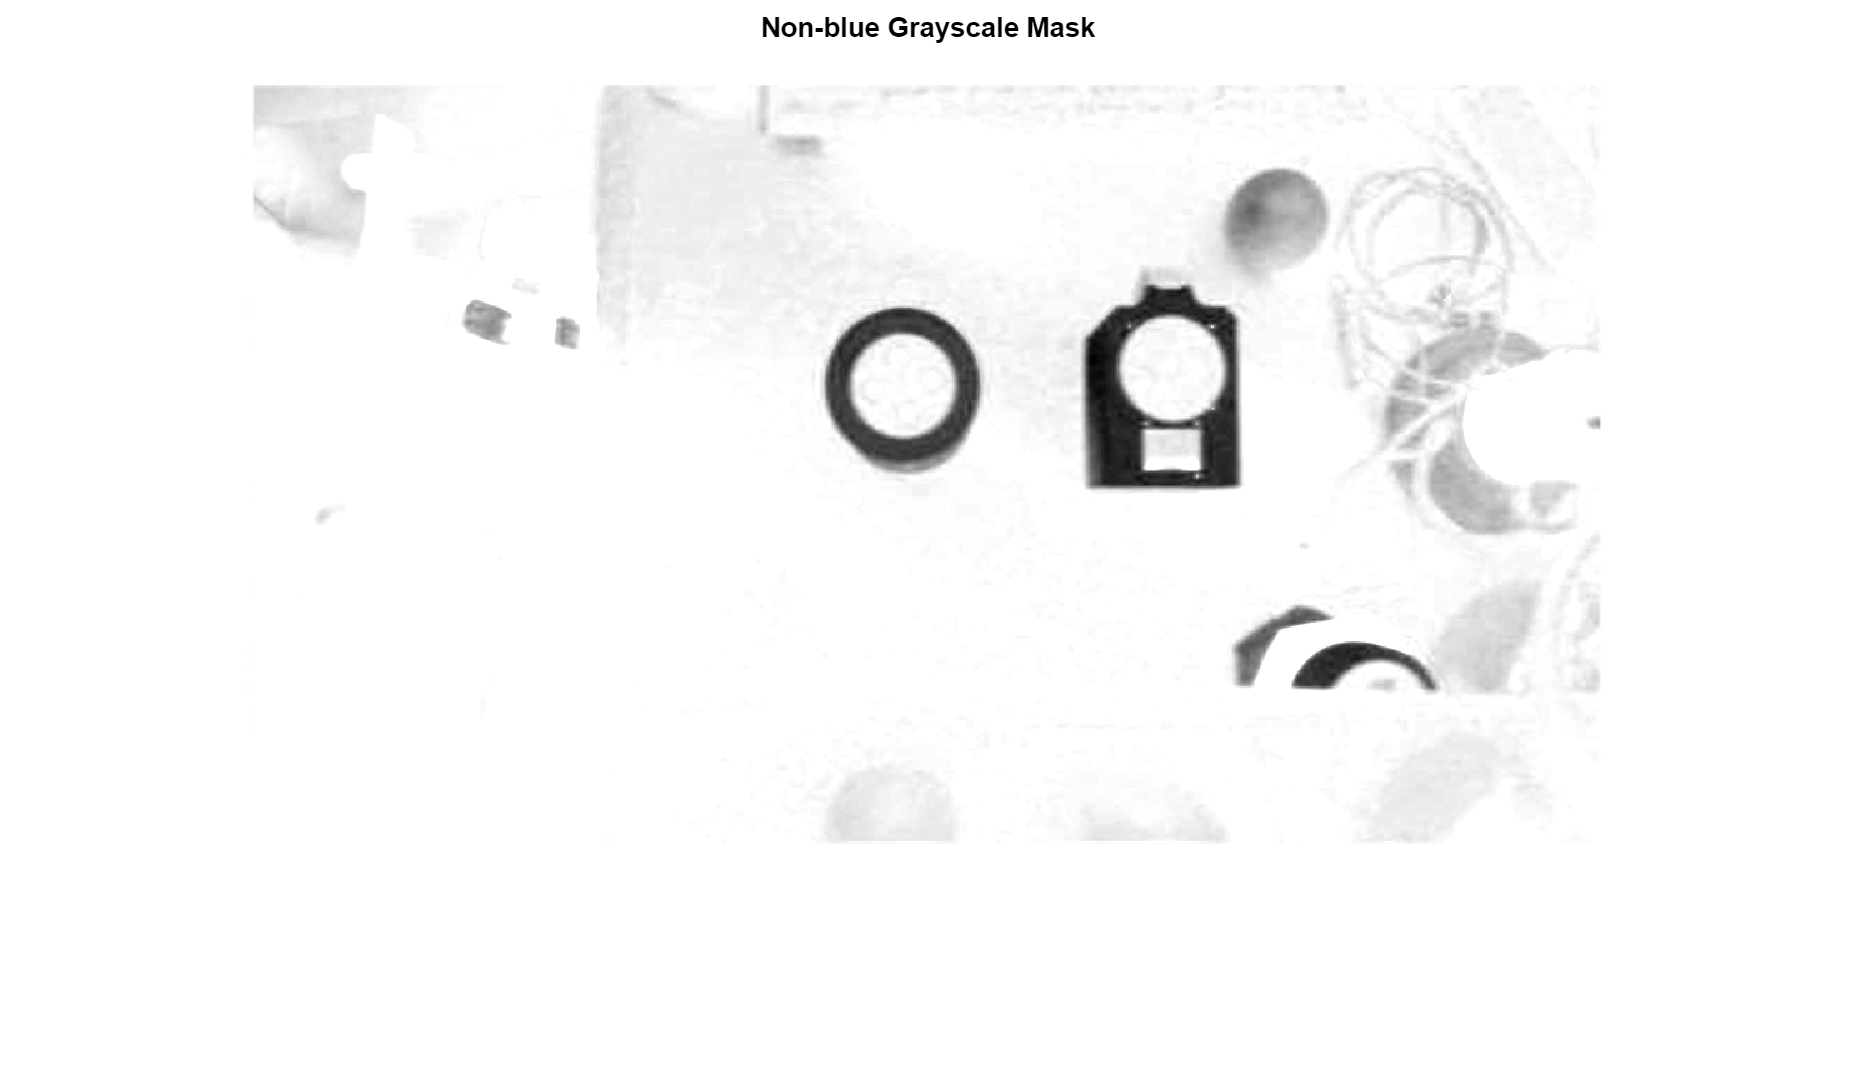



%% 4. Create "blue gradient" mask (nonBlueMask) and blur it
%    This will be used to detect black circles on a blue background.

% Convert to double for arithmetic
R = double(img(:, :, 1));
G = double(img(:, :, 2));
B = double(img(:, :, 3));

% Compute the "blue gradient" = B - max(R,G)
maxRG = max(R, G);
blueGrad = B - maxRG;
blueGrad(blueGrad < 0) = 0;  % Clip negative values

% Normalize to [0, 255] and convert to uint8
normBlue = mat2gray(blueGrad);    % [0..1]
blueMask = im2uint8(normBlue);    % [0..255]

% Invert => non-blue regions become bright
nonBlueMask = 255 - blueMask;

% (Optional) Show the non-blue mask
if DEBUG
    figure;
    imshow(nonBlueMask);
    title('Non-blue Grayscale Mask');
end

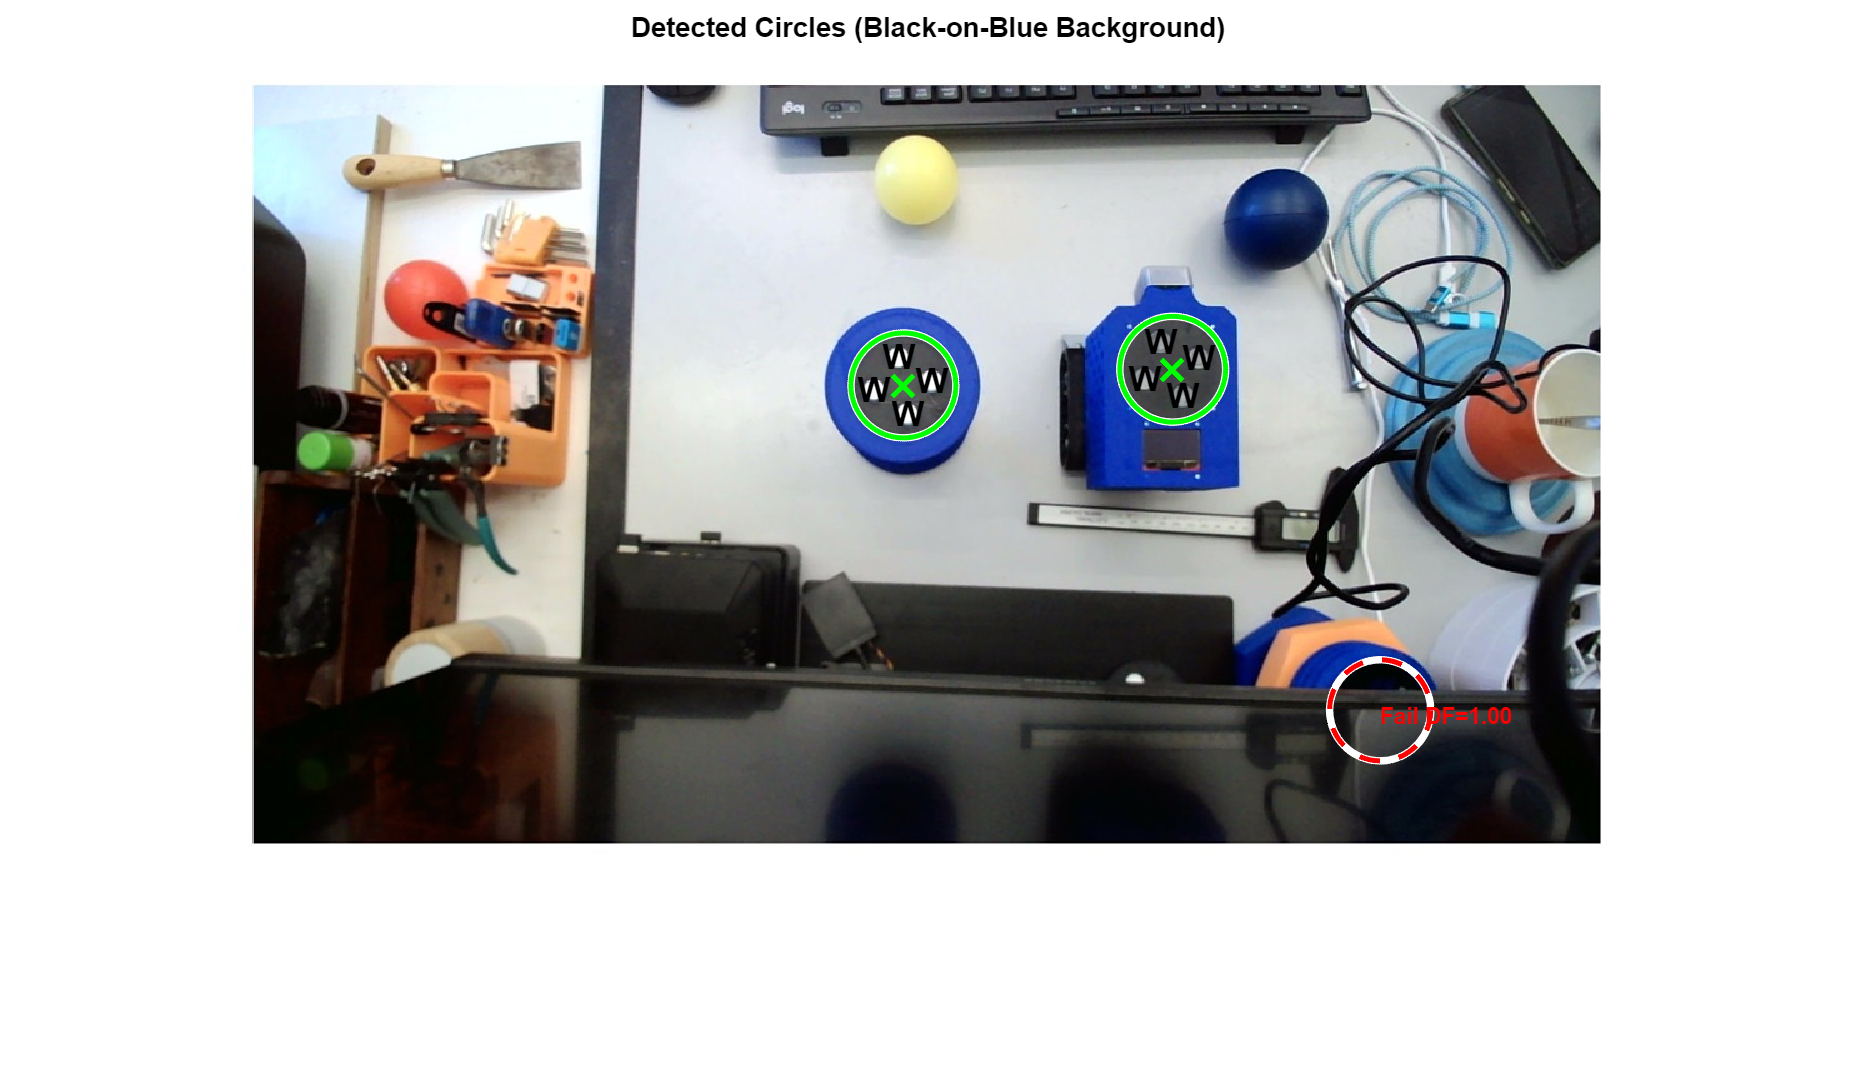

Valid Hub 1: Center=(613.2,271.8), Radius=42.0, DarkFraction=0.82, 4 blobs.
Valid Hub 2: Center=(828.7,258.8), Radius=42.3, DarkFraction=0.84, 4 blobs.


Circle 3 filtered out: DarkFraction=1.00



% Median blur to reduce noise
nonBlueMaskBlur = medfilt2(nonBlueMask, [5 5]);

%% 5. Detect circles in nonBlueMaskBlur
% Adjust radius range [15 100] as needed for your circle size
[centers, radii, metric] = imfindcircles(nonBlueMaskBlur, [15 100], ...
    'ObjectPolarity', 'bright', 'Sensitivity', 0.8);

% Visualize circle detection
figure;
imshow(img);
hold on;
title('Detected Circles (Black-on-Blue Background)');

if ~isempty(centers)
    viscircles(centers, radii, 'Color', 'g');
end

%% 6. Prepare to store valid hubs
% Each valid hub will have center, radius, numBlobs, darkFraction, plus 4 blob subfields.
hubs = struct('center',{}, 'radius',{}, 'numBlobs',{}, 'darkFraction',{}, ...
    'blob1',{}, 'blob2',{}, 'blob3',{}, 'blob4',{});
validHubCount = 0;

%% 7. Process each candidate hub to see if it has exactly 4 internal blobs
for i = 1:length(radii)
    c = centers(i, :);  % candidate hub center [x,y]
    r = radii(i);       % candidate hub radius
    
    % Create a circular mask for this candidate hub in "binImg" coordinates
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Calculate "darkFraction" based on binImg
    % binImg=1 => originally dark in the grayscale image
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;

    % Example range for darkFraction check
    if darkFraction >= 0.77 && darkFraction <= 0.9
        
        % ---- LED Blob Detection within the candidate hub ----
        % Force pixels outside the circle to white=1
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % Inside the hub, LED markers appear as black=0
        blackRegion = (hubSubImage == 0);
        
        % Morphological opening to remove small noise
        se = strel('disk', 2); % Adjust disk radius as needed
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components in the smoothed hub
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum area (in pixels) for a valid LED blob
        minBlobArea = 50;
        
        validCentroids = [];
        validColors = {}; 
        colorThreshold = 30;  % difference threshold for 'white'
        
        % Loop through each detected blob in the candidate hub
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                % Save the centroid
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
                
                % Indices of the pixels in this blob
                blobIndices = CC.PixelIdxList{j};
                
                % Compute mean R, G, B from the original color image
                R_channel = img(:,:,1);
                G_channel = img(:,:,2);
                B_channel = img(:,:,3);
                meanR = mean(double(R_channel(blobIndices)));
                meanG = mean(double(G_channel(blobIndices)));
                meanB = mean(double(B_channel(blobIndices)));
                
                % Classify the blob color
                if abs(meanR - meanG) < colorThreshold && ...
                   abs(meanR - meanB) < colorThreshold && ...
                   abs(meanG - meanB) < colorThreshold
                    blobColor = 'white';
                elseif meanR > meanG && meanR > meanB
                    blobColor = 'red';
                elseif meanG > meanR && meanG > meanB
                    blobColor = 'green';
                elseif meanB > meanR && meanB > meanG
                    blobColor = 'blue';
                else
                    blobColor = 'unknown';
                end
                
                validColors{end+1} = blobColor; %#ok<AGROW>
            end
        end
        
        numBlobs = size(validCentroids, 1);
        
        % ---- Require exactly 4 LED markers inside the hub ----
        if numBlobs == 4
            % Sort the 4 blobs in clockwise order, defining "up" as 0°
            angles = zeros(numBlobs, 1);
            for k = 1:numBlobs
                dX = validCentroids(k,1) - c(1);
                dY = validCentroids(k,2) - c(2);
                % Use atan2(dX, -dY) so 0° is "up" (negative Y)
                angles(k) = mod(atan2(dX, -dY), 2*pi);
            end
            [~, sortOrder] = sort(angles);
            sortedCentroids = validCentroids(sortOrder, :);
            sortedColors = validColors(sortOrder);
            
            % Store this valid hub
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).darkFraction = darkFraction;
            for k = 1:numBlobs
                fieldName = sprintf('blob%d', k);
                hubs(validHubCount).(fieldName).center = sortedCentroids(k, :);
                hubs(validHubCount).(fieldName).color = sortedColors{k};
            end
            
            % Draw a solid green circle
            viscircles(c, r, 'Color', 'g');
            plot(c(1), c(2), 'gx', 'MarkerSize', 12, 'LineWidth', 2);
            
            % Annotate each of the 4 blobs with its first letter
            for k = 1:numBlobs
                blobLetter = upper(sortedColors{k}(1));  
                blobPos = sortedCentroids(k, :);
                text(blobPos(1), blobPos(2), blobLetter, ...
                     'Color', 'k', 'FontSize', 14, 'FontWeight', 'bold', ...
                     'HorizontalAlignment','center');
            end
            
            fprintf('Valid Hub %d: Center=(%.1f,%.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % Candidate hub passed darkFraction check but did not have 4 blobs
            if DEBUG
                viscircles(c, r, 'Color', 'r', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), ...
                    'Color','r','FontWeight','bold','FontSize',9);
            end
            fprintf('Candidate hub at (%.1f,%.1f), R=%.1f => %d blobs (DarkFraction=%.2f)\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % Candidate hub fails darkFraction range
        if DEBUG
            viscircles(c, r, 'Color','r','LineStyle','--');
            text(c(1), c(2)+5, sprintf('Fail DF=%.2f', darkFraction), ...
                'Color','r','FontWeight','bold','FontSize',9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 8. Display the final structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×2 struct array with fields:

    center
    radius
    numBlobs
    darkFraction
    blob1
    blob2
    blob3
    blob4

